% Exercise 1.  Creating a waveform with an integer number of cycles 
input = linspace(0,999/1000,1000);
signal = 10 * cos(2*pi*300*input);

% Calculate and plot the FFT of your waveform.
fastFT = fft(signal);
%Verify numerically, using the FFT data, that you have created the required waveform
abs(fastFT(301))

ans = 5.0000e+03

invFT = 2 * abs(fastFT(301)) / 1000

invFT = 10.0000

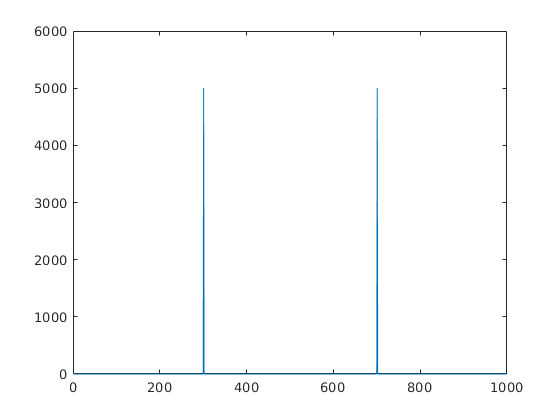


plot(abs(fastFT))

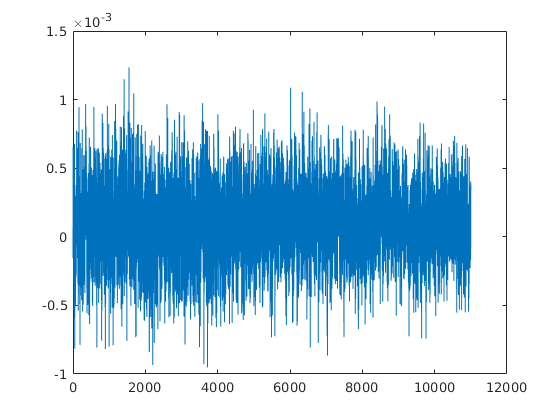

%xlim([297.17 305.34])
%ylim([0.0 11.4])


% Exercise 2.  Identification of a signal in noise

% Plot the data
plot(y)

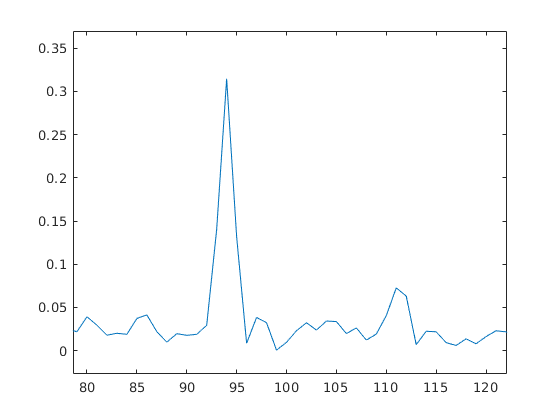

% Can you visually identify any periodic component?
% not easily, the data is very noisy. we can zoom in tho.

% Calculate and plot the FFT of the data.
% Ensure you use a window function to modify your data before calculating the FFT. 
fastFT2 = fft(y.*hamming(length(y))');
plot(abs(fastFT2));
% What is the frequency of the sinusoidal "signal” component?
% there is a spectrum peak at 94 
xlim([78.6 122.1])
ylim([-0.027 0.370])


% What is the calculated amplitude of the "signal” component?
% How does this compare to actual sinusoidal signal component used to create the data?
%the correction factor is 2 
% source: https://au.mathworks.com/matlabcentral/answers/372516-calculate-windowing-correction-factor

% the result matches the order of magnitude of the visible Amplitude in the original data plot
A2 = 2 * abs(fastFT2(94)) * 2 / length(y)

A2 = 1.1445e-04


% Using the DC term in the FFT, calculate the expected average value of the data. 
% How does this compare to the average value calculated conventionally?
 exp_average = 1 / (length(y) * abs(fastFT2(1)))

exp_average = 1.4761e-04

 coventional_average = mean(y)

coventional_average = 1.0000e-04

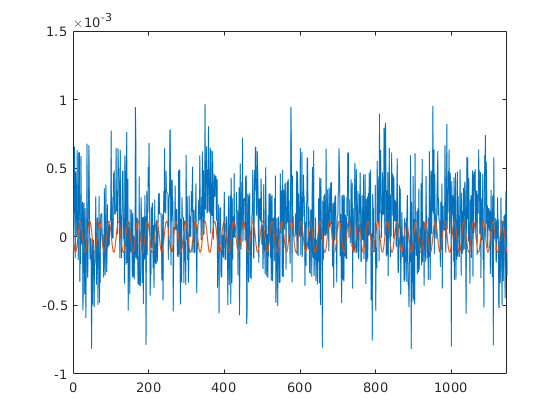

% it is of similar order of magnitude to the data average.

% On the same plot scale, plot the data and also a sinusoid with the same amplitude
% and frequency as the "signal” component. Note the extremely poor signal to noise ratio!
x = 1:length(y);
plot(x, y, x, A2 * sin(94 * x))
xlim([0 1147])
ylim([-0.00100 0.00150])


% Estimate the signal-to-noise ratio in the passband of the "signal” by examining the FFT spectrum.
noise_avg = mean(abs(fastFT2(50:100)));
signal_avg = mean(abs(fastFT2(94)));
Signal_to_Noise1 = signal_avg / noise_avg

Signal_to_Noise1 = 9.5791

% Compare this value to an estimate of the signal-to-noise ratio for the amplitude spectrum 
noise = std(y);
signal = std(A2 * sin(94 * x));
Signal_to_Noise2 = signal / noise

Signal_to_Noise2 = 0.2995

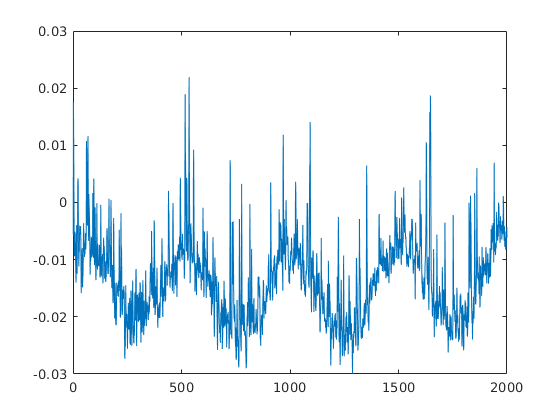



% Exercise 3.  Filtering a noisy signal.
% Plot the data. Can you visually identify the slow sinusoidal "signal” component?
plot(x2,y2)

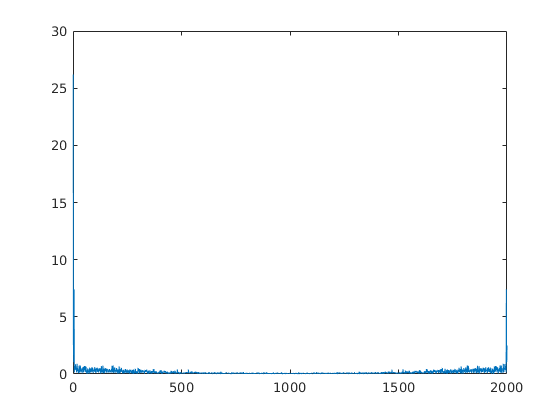


% Calculate and plot the FFT of the data. 
% Note: Ensure that your data is reduced to an even number of samples 
% and that you use a window function with your data before calculating the FFT
x3 = x2(1:2000);
y3 = y2(1:2000);
window = tukeywin(2000,0.1);
fastFT3 = fft(y3.*window);
plot(x2, abs(fastFT3))

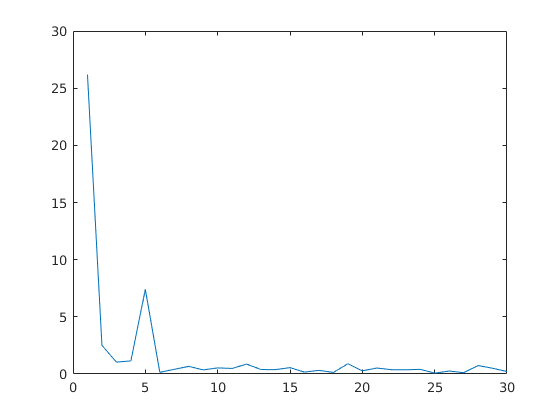


% In the frequency spectrum, identify the frequency terms corresponding to the signal.
plot(x2(1:30), abs(fastFT3(1:30)))

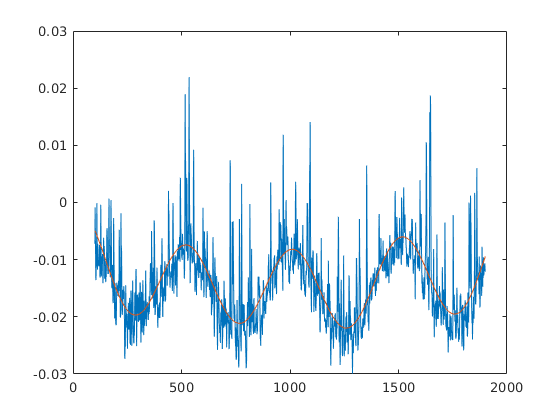

% Is the spectrum corresponding to the slowly-varying signal component obvious?
% frequencies appear to be less than 5.

% Create a filter for the frequency spectrum that will retain all the low-frequency signal information
filter = zeros(2000,1);
filter(1:6) = 1;
filter(2000-6+2:2000) = 1;

% Recover the signal component from the data using the inverse FFT of your filtered spectrum.
filtered_signal = ifft(fastFT3.*filter);

% On the same graph, plot your original data and your filtered signal. Note: restrict your plot 
% to the data region unaffected by the window function. (Hint: use find on your window function vector
% to identify regions where the vector has the value 1).
% Based on a visual inspection, have you effectively removed the signal from the noise?
index=find(window==1);
plot(x3(index),y3(index),x3(index),filtered_signal(index))

% :D yes I found it!